# **Calculate M and Theta (several equations, 2 solutions)**

This script calculates an approximate solution from several inputs of noise g's and v's.

**Last Update:** 04/Mar/2020

## **Addpaths**

clear all
clc
close all
addpath(genpath('C:\Users\Rita\Documents\MATLAB\spm8'))
path ='C:\Users\Rita\Desktop\CHUV_Tests';
addpath(genpath(path))
cd(path)

## Load data 

Load g-ratio data to get a standard deviation for the simulations that closely match the ones in real life

close all

% Load files
cd(fullfile(path,'Example_images'))
file = dir('g_ratio.nii');
header = spm_vol(file.name);
gratio = spm_read_vols(header);

file = dir('Occipital_mask_tract.nii');
header = spm_vol(file.name);
tract = spm_read_vols(header);

% Get g-ratio values in tract
g_map = gratio.*tract;
G     = g_map(find(g_map>0));

% Fit normal distirbution to data
G_normal    = fitdist(G,'Normal');
g_mean      = G_normal.mu;
g_std       = G_normal.sigma;

sprintf('In real data we get a mean of %0.02f and a standard deviation of %0.02f',g_mean,g_std)

ans = 'In real data we get a mean of 0.70 and a standard deviation of 0.05'

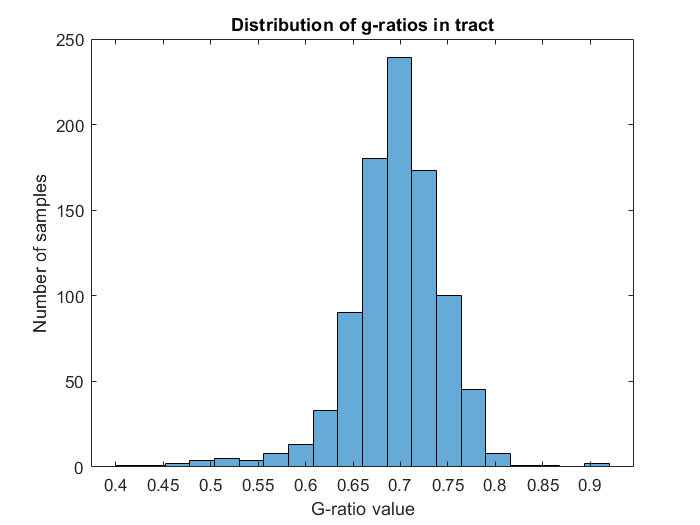

% Plot distribution of g's in data
figure()
histogram(G,20)
ylabel('Number of samples')
xlabel('G-ratio value')
title('Distribution of g-ratios in tract')

**Comments:**

From now on, we will use this standard deviation (0.05) and mean to do our simulatiosn the most close to reality as possible.

## Several Equations 1 & One Equation 2 - simulated g's - Testing solver functions

% Initiate (run only once to use the same G's all the time)
g       = 0.7;
v       = 10;
alpha   = 0.1;
beta    = 0.7;
npoints = 100;
G_raw   = g*ones(npoints,1);
G       = normrnd(0.7,0.05,[npoints,1]);  % Make gaussian noise on g's with mean 0.7 and std 0f 0.02.

% Solve equations with fsolve
x0      = [0.3;0.2]; % First guess on M and theta
options = optimoptions('fsolve','Display','iter','FunctionTolerance',10^-7,'OptimalityTolerance',10^-6,'algorithm','trust-region','TypicalX',[0.3; 0.1]);
res1    = fsolve(@(x) make_equations_gv(x,alpha,beta,G,[v]),x0,options);


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          3         3.42604                          26.3
     1          6        0.427545      0.0882236          0.296      
     2          9        0.427007      0.0111265       6.64e-05      
     3         12        0.427007     7.7193e-05       6.61e-09      

No solution found.

fsolve stopped because the problem appears regular as measured by the gradient,
but the vector of function values is not near zero as measured by the
value of the 

% Solve equations with lsqnonlin
options = optimoptions('lsqnonlin','Display','iter','FunctionTolerance',10^-7,'OptimalityTolerance',10^-6,'algorithm','trust-region-reflective');
[res2 fval residual exitflag]    = lsqnonlin(@(x) make_equations_gv(x,alpha,beta,G,[v]),x0,[0.1 0],[1 1],options); % other option


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          3         3.42604                          20.4
     1          6        0.448213      0.0877025           1.52      
     2          9        0.427448       0.011878         0.0214      
     3         12        0.427007      0.0235936       0.000219      
     4         15        0.427007    0.000527834       3.83e-08      

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<

% Get values of M and Theta
M_with_noise_f        = res1(1);
Theta_with_noise_f    = res1(2);
M_with_noise_l        = res2(1);
Theta_with_noise_l    = res2(2);
sprintf('fsolver - Mode is: %.003f and Theta is: %.003f and \n lsqnonlin - Mode is: %.003f and Theta is: %.003f',M_with_noise_f,Theta_with_noise_f,M_with_noise_l,Theta_with_noise_l)

ans =     'fsolver - Mode is: 0.375 and Theta is: 0.242 and 
      lsqnonlin - Mode is: 0.375 and Theta is: 0.242'


**Comments**:

Both solvers give the same solution, though the fsolver says that he can't find a solution and the other says that it found a minimum. I think it happens because of the inerent difference between the mehtods, while fsolver tries to find an exact solution, lsqnonlin only tries to minimize the difference between the solutions.

## Several Equations 1 & One Equation 2 - simulated g's - Testing solver algorithms

% Initiate (run only once to use the same G's all the time)
g       = 0.7;
v       = 10;
alpha   = 0.1;
beta    = 0.7;
npoints = 100;
G_raw   = g*ones(npoints,1);
G       = normrnd(0.7,0.05,[npoints,1]);  % Make gaussian noise on g's with mean 0.7 and std 0f 0.02.

% Solve equations
x0      = [0.3;0.2]; % First guess on M and theta
options = optimoptions('lsqnonlin','Display','iter','FunctionTolerance',10^-7,'OptimalityTolerance',10^-6,'algorithm','trust-region-reflective');
res1    = lsqnonlin(@(x) make_equations_gv(x,alpha,beta,G,[v]),x0,[],[],options);


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          3         3.61765                          26.5
     1          6        0.538661       0.120685          0.341      
     2          9        0.536596       0.041018        0.00153      
     3         12        0.536596    0.000738824       5.31e-07      

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<

x0      = [0.3;0.2]; % First guess on M and theta
options = optimoptions('lsqnonlin','Display','iter','FunctionTolerance',10^-7,'OptimalityTolerance',10^-6,'algorithm','trust-region-reflective');
res2    = lsqnonlin(@(x) make_equations_gv(x,alpha,beta,G,[v]),x0,[],[],options);


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          3         3.61765                          26.5
     1          6        0.538661       0.120685          0.341      
     2          9        0.536596       0.041018        0.00153      
     3         12        0.536596    0.000738824       5.31e-07      

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<


% Get values of M and Theta
M_with_noise_t        = res1(1);
Theta_with_noise_t    = res1(2);
M_with_noise_l        = res2(1);
Theta_with_noise_l    = res2(2);
sprintf('trust-region-reflective - Mode is: %.003f and Theta is: %.003f and \n levenberg-marquardt - Mode is: %.003f and Theta is: %.003f',M_with_noise_t,Theta_with_noise_t,M_with_noise_l,Theta_with_noise_l)

ans =     'trust-region-reflective - Mode is: 0.270 and Theta is: 0.351 and 
      levenberg-marquardt - Mode is: 0.270 and Theta is: 0.351'


**Comments:**

Both algorithms seem to provide the same solution. Also, this is just a preference. 

Recommendations from Matlab:

- Generally, try `'trust-region-reflective'` first. If your problem has bounds, you must use `'trust-region-reflective'`.

- If your problem has no bounds and is underdetermined (fewer equations than dimensions), use `'levenberg-marquardt'`.

## Several Equations 1 & One Equation 2 - simulated g's - Testing initial guesses

% Initiate (run only once to use the same G's all the time)
g       = 0.7;
v       = 10;
alpha   = 0.1;
beta    = 0.7;
npoints = 100;
G_raw   = g*ones(npoints,1);
G       = normrnd(0.7,0.05,[npoints,1]);  % Make gaussian noise on g's with mean 0.7 and std 0f 0.02.
X0      = [0.3 0.1; 0.3 0.2; 0.4 0.1; 0.4 0.2; 0.5 0.1; 0.5 0.5];
Color_list  = [0, 0.4470, 0.7410; 0.8500, 0.3250, 0.0980; 0.9290, 0.6940, 0.1250; 0.4940, 0.1840, 0.5560; 0.4660, 0.6740, 0.1880; 0.3010, 0.7450, 0.9330; 0.6350, 0.0780, 0.1840; 0.4660, 0.6740, 0.1880];


figure()

% Loop over X0s
for i=1:length(X0)
    x0  = X0(i,:);
    
    % Solve equations
    options = optimoptions('lsqnonlin','FunctionTolerance',10^-7,'OptimalityTolerance',10^-6,'algorithm','trust-region-reflective');
    res    = lsqnonlin(@(x) make_equations_gv(x,alpha,beta,G,[v]),x0,[0 0],[1 1],options); % other option
    
    % Get values of M and Theta
    M_with_noise        = res(1);
    Theta_with_noise    = res(2);
    sprintf('Mode is: %.003f and Theta is: %.003f',M_with_noise,Theta_with_noise)
    scatter(res(1),res(2),'MarkerFaceColor',Color_list(i,:))
    hold on
    
end


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


ans = 'Mode is: 0.393 and Theta is: 0.222'


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


ans = 'Mode is: 0.393 and Theta is: 0.222'


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


ans = 'Mode is: 0.393 and Theta is: 0.222'


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


ans = 'Mode is: 0.393 and Theta is: 0.222'


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


ans = 'Mode is: 0.393 and Theta is: 0.222'


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


ans = 'Mode is: 0.393 and Theta is: 0.222'

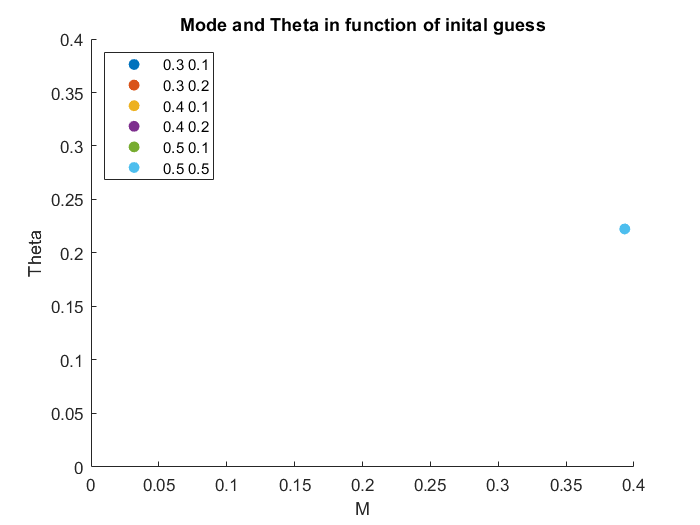

xlabel('M')
ylabel('Theta')
xlim([0 0.4])
ylim([0 0.4])
title('Mode and Theta in function of inital guess')
legend('0.3 0.1','0.3 0.2','0.4 0.1','0.4 0.2','0.5 0.1','0.5 0.5','Location','northwest')

**Comments:**

It seems that the algortihm is not that sensitive to initial guesses.

## Several Equations 1 & One Equation 2 - simulated g's - Testing boundary limits

% Initiate (run only once to use the same G's all the time)
g       = 0.7;
v       = 10;
alpha   = 0.1;
beta    = 0.7;
npoints = 300;
G_raw   = g*ones(npoints,1);
G       = normrnd(0.7,0.05,[npoints,1]);  % Make gaussian noise on g's with mean 0.7 and std 0f 0.02.
x0      = [0.2 0.2];
Xlim    = [0 0 1 1; 0.1 0.1 1 1; 0.1 0.1 0.5 0.5; 0.2 0 0.5 0.3];
Color_list  = [0, 0.4470, 0.7410; 0.8500, 0.3250, 0.0980; 0.9290, 0.6940, 0.1250; 0.4940, 0.1840, 0.5560; 0.4660, 0.6740, 0.1880; 0.3010, 0.7450, 0.9330; 0.6350, 0.0780, 0.1840; 0.4660, 0.6740, 0.1880];

figure()

% Loop over limits of X
for i=1:length(Xlim)+1
    
    % Solve equations
    options = optimoptions('lsqnonlin','FunctionTolerance',10^-7,'OptimalityTolerance',10^-6,'algorithm','trust-region-reflective');
    
    if i==length(Xlim)+1
        res     = lsqnonlin(@(x) make_equations_gv(x,alpha,beta,G,[v]),x0,[],[],options); % other option
        
    else
        res     = lsqnonlin(@(x) make_equations_gv(x,alpha,beta,G,[v]),x0,[Xlim(i,1) Xlim(i,2)],[Xlim(i,3) Xlim(i,4)],options); % other option
        
    end
    
    % Get values of M and Theta
    M_with_noise        = res(1);
    Theta_with_noise    = res(2);
    sprintf('Mode is: %.003f and Theta is: %.003f',M_with_noise,Theta_with_noise)
    scatter(res(1),res(2),'MarkerFaceColor',Color_list(i,:))
    hold on
    
end


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


ans = 'Mode is: 0.350 and Theta is: 0.267'


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


ans = 'Mode is: 0.350 and Theta is: 0.267'


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


ans = 'Mode is: 0.350 and Theta is: 0.267'


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


ans = 'Mode is: 0.350 and Theta is: 0.267'


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


ans = 'Mode is: 0.350 and Theta is: 0.267'

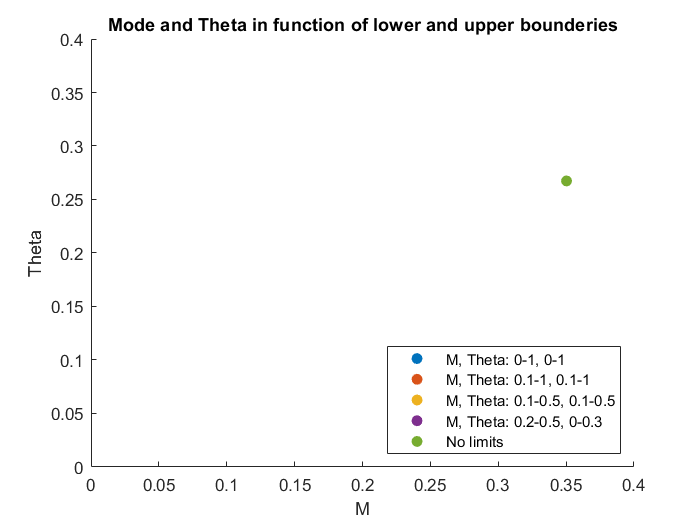

xlabel('M')
ylabel('Theta')
xlim([0 0.4])
ylim([0 0.4])
title('Mode and Theta in function of lower and upper bounderies')
legend('M, Theta: 0-1, 0-1','M, Theta: 0.1-1, 0.1-1','M, Theta: 0.1-0.5, 0.1-0.5','M, Theta: 0.2-0.5, 0-0.3','No limits','Location','southeast')

**Comments:**

Se colocar limite superior em theta em 0.3 por exemplo, ele encontra como solução 0.3, porque é o limite, no entanto, de verdade ele deveria ir mais acima, que é o que acontece se deixarmos como limite superior a 1. No entanto também parece indiferente que limite colocamos, desde que seja entre 0 e 1. Também é indiferente colocar ou não colocar limites.

## Several Equations 1 & One Equation 2 - simulated g's - Visualize # g's 

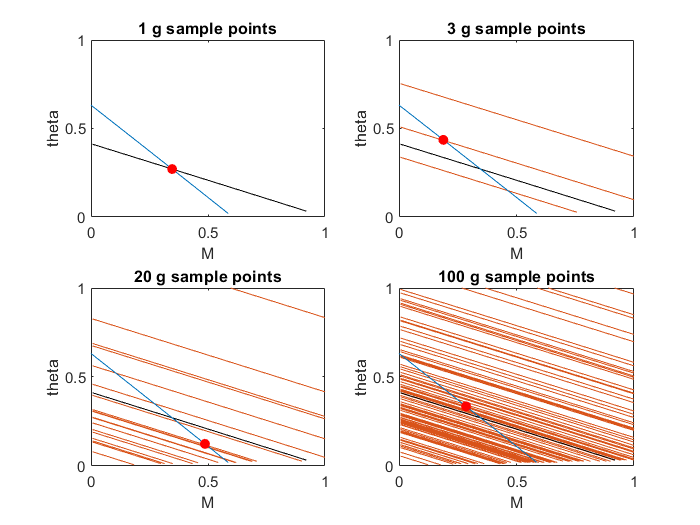

npoints_list = [1,3,20,100]; % number of g equations
figure()

% Loop for g number of equations
for i=1:length(npoints_list)
    subplot(2,2,i)
    
    % Initiate
    g       = 0.7;
    v       = 10;
    alpha   = 0.1;
    beta    = 0.7;
    npoints = npoints_list(i);
    if npoints==1 % The first plot corresponds to g=0.7;
        G=[0.7];
    else
        G_raw   = g*ones(npoints,1);
        G       = normrnd(g,0.05,[npoints,1]);  % Make gaussian noise on g's with mean 0.7 and std 0f 0.05
    end
    
    % Make equations for all g's and plot (true g and noise)
    for j=1:length(G)
        g=G(j);
        warning('off')
        fimplicit(@(M,theta) make_equations_g_plot(M,theta,g,alpha,beta),'Color',[0.8500, 0.3250, 0.0980]);
        hold on
        fimplicit(@(M,theta) make_equations_g_plot(M,theta,0.7,alpha,beta),'Color','k');
        hold on
        
    end
    
    warning('off')
    fimplicit(@(M,theta) make_equations_v_plot(M,theta,v,alpha,beta),'Color',[0, 0.4470, 0.7410]);
    hold on
    
    xlim([0,1])
    ylim([0,1])
    xlabel('M')
    ylabel('theta')
    title(sprintf('%d g sample points',npoints))
    
    % Solve equations for noise
    x0      = [0.3;0.1]; % First guess on M and theta
    options = optimoptions('lsqnonlin','Display','Off','FunctionTolerance',10^-7,'OptimalityTolerance',10^-6,'algorithm','trust-region-reflective');
    res    = lsqnonlin(@(x) make_equations_gv(x,alpha,beta,G,[v]),x0,[0.1 0],[1 1],options); % other option
    
    % Get values for M and theta
    M_with_noise        = res(1);
    Theta_with_noise    = res(2);
    
    % Plot solution found
    scatter(M_with_noise,Theta_with_noise,'r','Filled')
    hold on
    
end

% Save figure
saveas(gcf,fullfile(path,'ImagesResults','Visualize Equations - g noise.png'))

**Comments:**

Fisrt, the solution travels along the velocity line. 

We can see that with few equations, since those lines are below the 0.7 that is the true g, the solution is "pushed down", due to those equations.

With more equations (a dense normal distribution) the majority of the g's are located around the true g, therefore the solution found is quite similar to the true one.

## One Equation 1 & Several Equations 2 - simulated v's - Visualize # v's 

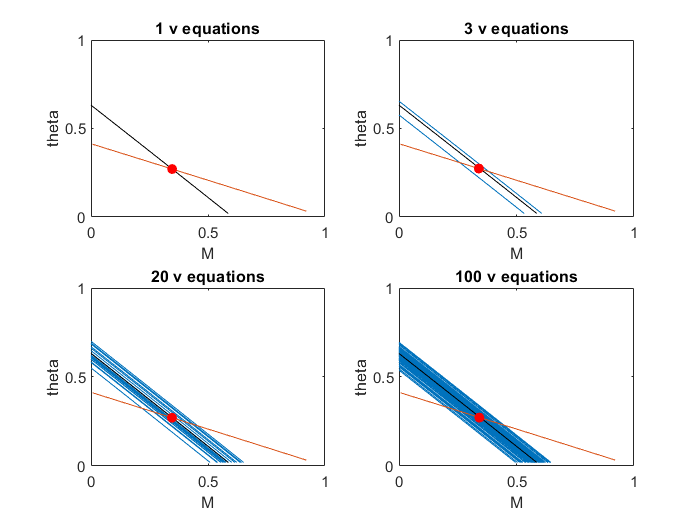

npoints_list = [1,3,20,100]; % number of g equations
figure()

% Loop for g number of equations
for i=1:length(npoints_list)
    subplot(2,2,i)
    
    % Initiate
    g       = 0.7;
    v       = 10;
    alpha   = 0.1;
    beta    = 0.7;
    npoints = npoints_list(i);
    if npoints==1 % The first plot corresponds to v=7;
        V=10;
    else
        V_raw   = v*ones(npoints,1);
        V       = normrnd(v,0.5,[npoints,1]);  % Make gaussian noise on v's with mean 7 and std 0f 0.5
    end
    
    % Make equations for all v's and plot (true g and noise)
    for j=1:length(V)
        v=V(j);
        
        warning('off')
        fimplicit(@(M,theta) make_equations_v_plot(M,theta,v,alpha,beta),'Color',[0, 0.4470, 0.7410]);
        warning('off')
        fimplicit(@(M,theta) make_equations_v_plot(M,theta,10,alpha,beta),'Color','k');
        hold on
        
    end
    
    % Make equation for g and plot
    warning('off')
    fimplicit(@(M,theta) make_equations_g_plot(M,theta,g,alpha,beta),'Color',[0.8500, 0.3250, 0.0980]);
    hold on
    
    xlim([0,1])
    ylim([0,1])
    xlabel('M')
    ylabel('theta')
    title(sprintf('%d v equations',npoints))
    
    % Solve equations for noise
    x0      = [0.3;0.1]; % First guess on M and theta
    options = optimoptions('lsqnonlin','Display','Off','FunctionTolerance',10^-7,'OptimalityTolerance',10^-6,'algorithm','trust-region-reflective');
    res    = lsqnonlin(@(x) make_equations_gv(x,alpha,beta,[g],V),x0,[0.1 0],[1 1],options); % other option
    
    % Get values for M and theta
    M_with_noise        = res(1);
    Theta_with_noise    = res(2);
    
    % Plot solution found
    scatter(M_with_noise,Theta_with_noise,'r','Filled')
    hold on
    
end
% Save figure
saveas(gcf,fullfile(path,'ImagesResults','Visualize Equations - v noise.png'))

**Comments:**

Fisrt, the solution travels along the g-ratio line. 

We can see the same as before. Thought now, the equations are more bound together, therefore the solution doesn't vary much. We had already seen that the same bias in the v equations didn't lead to such large differeences in the lines, this is due to the fact that that the g is squared in the eqautions (??).

## Several Equations 1 & One Equation 2 - simulated g's - Testing # g's functions and iterations

Testing for g=0.7 and v=7. Then adding gaussian noise to g's. Test the reprodibility with several iterations.

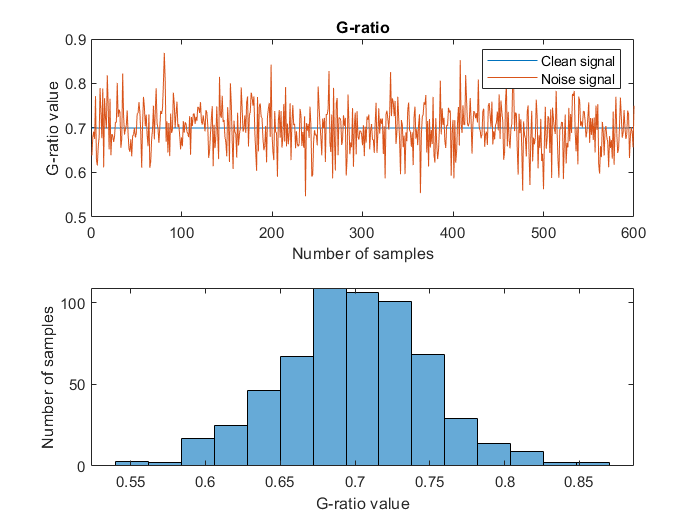

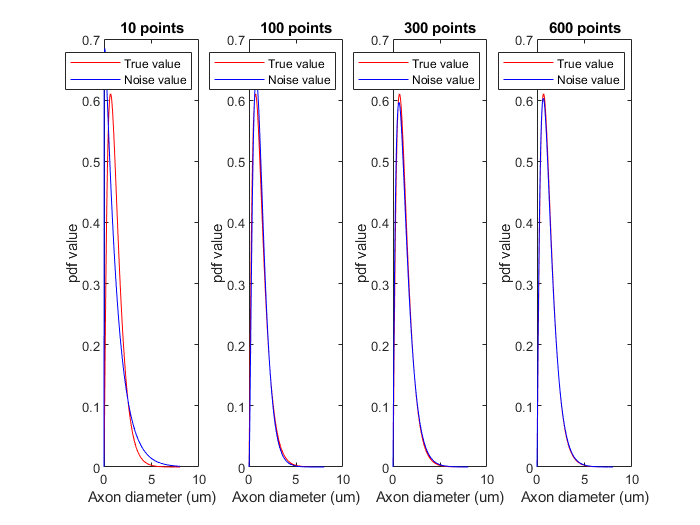

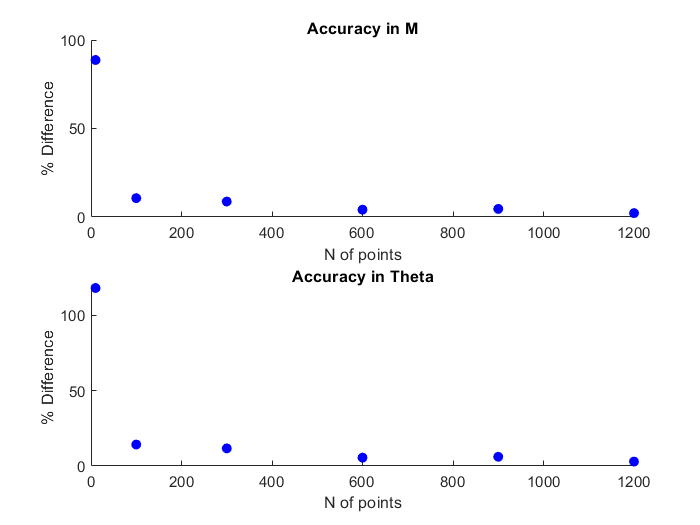

Diff_M      = [];
Diff_Theta  = [];
iter_list   = 1:500;
close all

% Loop for iterations
for iter=1:length(iter_list)
    npoints_list = [10,100,300,600,900,1200]; % number of g equations
    diff_M      = [];
    diff_theta  = [];
    figure(1)
    figure(2)
    figure(3)
    
    % Loop for g number of equations
    for i=1:length(npoints_list)
        
        % Initiate (run only once to use the same G's all the time)
        g       = 0.7;
        v       = 10;
        alpha   = 0.1;
        beta    = 0.7;
        npoints = npoints_list(i);
        G_raw   = g*ones(npoints,1);
        G       = normrnd(0.7,0.05,[npoints,1]);  % Make gaussian noise on g's with mean 0.7 and std 0f 0.02.
        
        
        % Plot noise example on g
        if i==4 && iter==1
            figure(1)
            subplot(2,1,1)
            plot(1:npoints,G_raw)
            hold on
            plot(1:npoints,G)
            title('G-ratio')
            xlabel('Number of samples')
            ylabel('G-ratio value')
            legend('Clean signal','Noise signal')
            subplot(2,1,2)
            histogram(G,15)
            ylabel('Number of samples')
            xlabel('G-ratio value')
            hold off
        end
        
        % Solve equations
        x0      = [0.3;0.1]; % First guess on M and theta
        options = optimoptions('lsqnonlin','Display','Off','FunctionTolerance',10^-7,'OptimalityTolerance',10^-6,'algorithm','trust-region-reflective');
        res    = lsqnonlin(@(x) make_equations_gv(x,alpha,beta,G,[v]),x0,[0 0],[1 1],options); % other option
        
        % Get values for M and theta
        M_with_noise        = res(1);
        Theta_with_noise    = res(2);
        
        sprintf('Solver - Mode is: %.003f and Theta is: %.003f',M_with_noise,Theta_with_noise);
        
        % Get real values of diameter and plot
        if iter==1
            [M_true, Theta_true] = GetRealSol_Plot(i,npoints_list,alpha,beta,g,v,M_with_noise,Theta_with_noise,[0 0 1],1);
        else
            [M_true, Theta_true] = GetRealSol_Plot(i,npoints_list,alpha,beta,g,v,M_with_noise,Theta_with_noise,[0 0 1],0);
        end
        
        % Diff
        diff_M      = [diff_M (abs(M_with_noise-M_true)/M_true)*100];
        diff_theta  = [diff_theta (abs(Theta_with_noise-Theta_true)/Theta_true)*100];
    end
    Diff_M      = [Diff_M; diff_M];
    Diff_Theta  = [Diff_Theta; diff_theta];
end

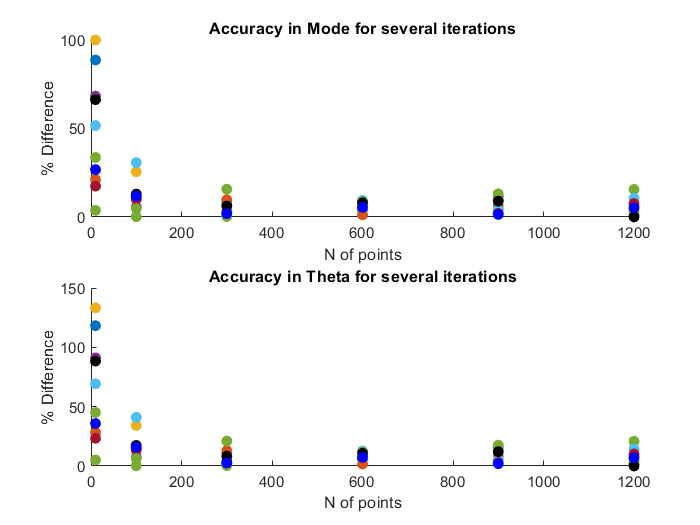

% Plot Reproducivility
Color_list      = [0, 0.4470, 0.7410; 0.8500, 0.3250, 0.0980; 0.9290, 0.6940, 0.1250; 0.4940, 0.1840, 0.5560; 0.4660, 0.6740, 0.1880; 0.3010, 0.7450, 0.9330; 0.6350, 0.0780, 0.1840; 0.4660, 0.6740, 0.1880; 0 0 0; 0 0 1];
figure(4)
for iter=1:10
    subplot(2,1,1)
    scatter(npoints_list,Diff_M(iter,:),'MarkerFaceColor',Color_list(iter,:),'MarkerEdgeColor',Color_list(iter,:))
    title('Accuracy in Mode for several iterations')
    xlabel('N of points')
    ylabel('% Difference')
    hold on
    subplot(2,1,2)
    scatter(npoints_list,Diff_Theta(iter,:),'MarkerFaceColor',Color_list(iter,:),'MarkerEdgeColor',Color_list(iter,:))
    title('Accuracy in Theta for several iterations')
    xlabel('N of points')
    ylabel('% Difference')
    hold on
    
end

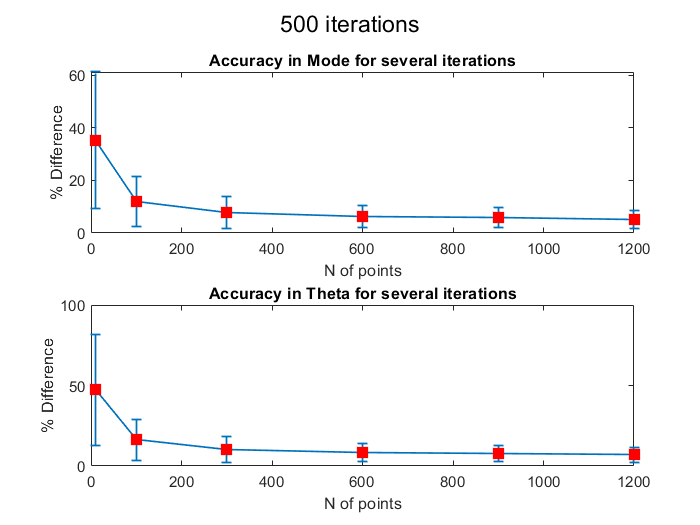

% Plot Reproducibility - with error bars
f = figure(5);
subplot(2,1,1)
errorbar(npoints_list,mean(Diff_M),std(Diff_M),'-s','MarkerSize',8,'MarkerEdgeColor','red','MarkerFaceColor','red','LineWidth',1)
title('Accuracy in Mode for several iterations')
xlabel('N of points')
ylabel('% Difference')
hold on
subplot(2,1,2)
errorbar(npoints_list,mean(Diff_Theta),std(Diff_Theta),'-s','MarkerSize',8,'MarkerEdgeColor','red','MarkerFaceColor','red','LineWidth',1)
title('Accuracy in Theta for several iterations')
xlabel('N of points')
ylabel('% Difference')
sgtitle(sprintf('%d iterations',max(iter_list)))
% Save figure
saveas(f,fullfile(path,'ImagesResults','Accuracy & Reproducibility- g noise.png'))

**Comments:**

The mode and theta values are quite similar to the true ones, using this method.

The more points we use, usually the better. Though, these relationship doesn't seem to be true always. 

This might be due to the fact that we don't have a random distribution on the G's, instead we are sampling random along a distribution of G's, so sometimes, the values that we get can be quite near the mean and therefore yield better results, and sometimes it can be wider and the results lead to worst results. --> Not true, we have a gaussian distribution on G's

## Several Equations 1 & Several Equation 2 - simulated g's and simulated v's - Testing # of g's and v's 

The number of g's and v's here are the same.

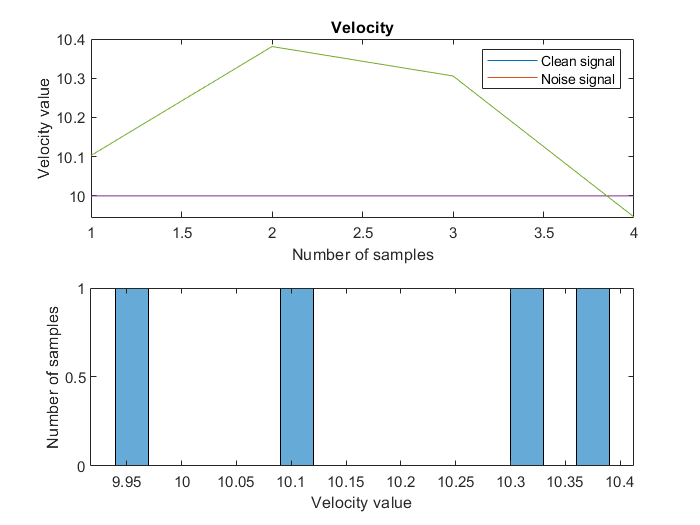

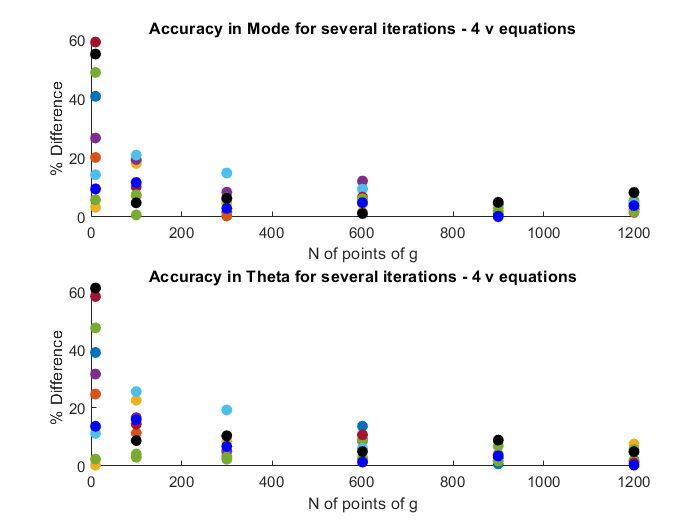

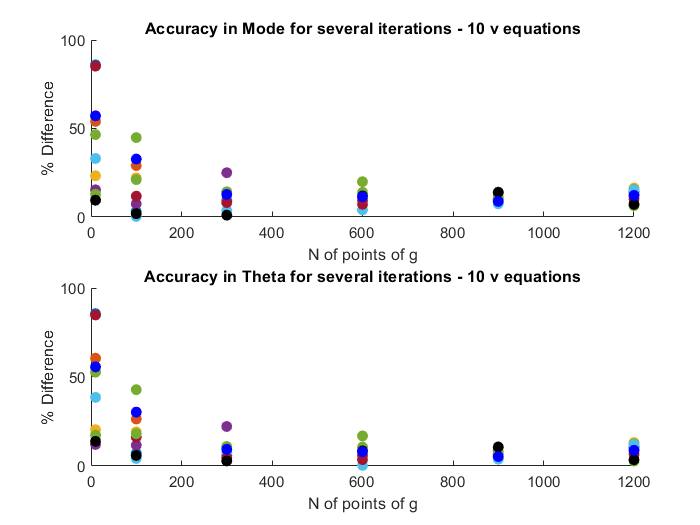

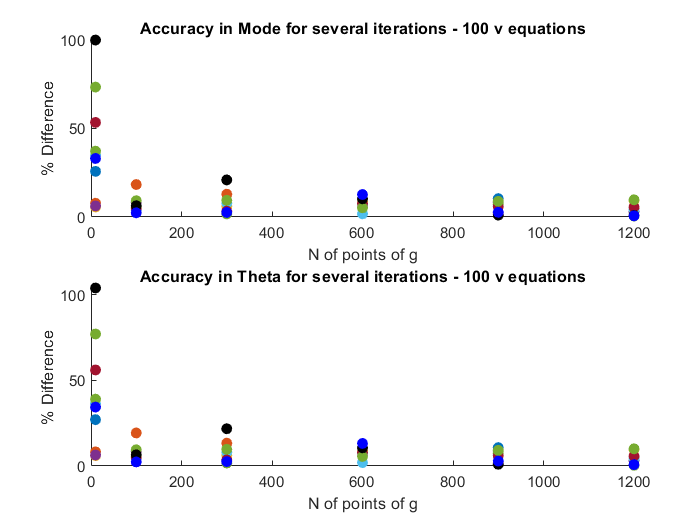

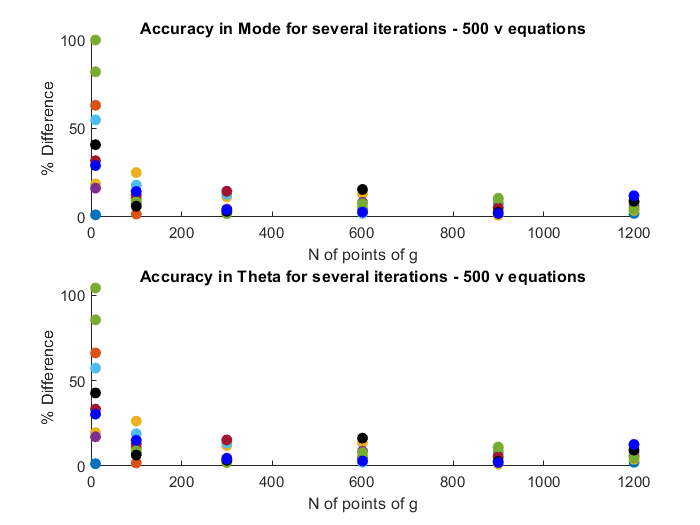

% Initiate
g               = 0.7;
v               = 10;
alpha           = 0.1;
beta            = 0.7;
iter_list       = 1:500;
Color_list      = [0, 0.4470, 0.7410; 0.8500, 0.3250, 0.0980; 0.9290, 0.6940, 0.1250; 0.4940, 0.1840, 0.5560; 0.4660, 0.6740, 0.1880; 0.3010, 0.7450, 0.9330; 0.6350, 0.0780, 0.1840; 0.4660, 0.6740, 0.1880; 0 0 0; 0 0 1];
npoints_list_g  = [10,100,300,600,900,1200]; % number of g equations
npoints_list_v  = [4,10,100,500]; % number of g equations
close all
Mean_M          = zeros(length(npoints_list_v),length(npoints_list_g));
Std_M           = zeros(length(npoints_list_v),length(npoints_list_g));
Mean_Theta      = zeros(length(npoints_list_v),length(npoints_list_g));
Std_Theta       = zeros(length(npoints_list_v),length(npoints_list_g));

% Loop for v number of equations
for i_v=1:length(npoints_list_v)
    npoints = npoints_list_v(i_v);
    V       = normrnd(v,0.2,[npoints,1]);  % Make gaussian noise on v's with mean 7 and std of 0.2.
    
    % Plot noise example on v
    if i_v==1
        figure(1)
        subplot(2,1,1)
        plot(1:npoints_list_v(i_v),ones(npoints_list_v(i_v))*v)
        hold on
        plot(1:npoints_list_v(i_v),V)
        title('Velocity')
        xlabel('Number of samples')
        ylabel('Velocity value')
        legend('Clean signal','Noise signal')
        subplot(2,1,2)
        histogram(V,15)
        ylabel('Number of samples')
        xlabel('Velocity value')
        hold off
    end
    
    Diff_M      = [];
    Diff_Theta  = [];
    
    % Loop for iterations
    for iter=1:length(iter_list)
        diff_M      = [];
        diff_theta  = [];
        figure(1)
        
        % Loop for g number of equations
        for i_g=1:length(npoints_list_g)
            npoints = npoints_list_g(i_g);
            G       = normrnd(g,0.05,[npoints,1]);  % Make gaussian noise on g's with mean 0.7 and std 0f 0.02.
            
            % Solve equations
            x0      = [0.3;0.1]; % First guess on M and theta
            options = optimoptions('lsqnonlin','Display','Off','FunctionTolerance',10^-7,'OptimalityTolerance',10^-6,'algorithm','trust-region-reflective');
            res    = lsqnonlin(@(x) make_equations_gv(x,alpha,beta,G,V),x0,[0 0],[1 1],options); % other option
            
            % Get values for M and theta
            M_with_noise        = res(1);
            Theta_with_noise    = res(2);
            
            sprintf('Solver - Mode is: %.003f and Theta is: %.003f',M_with_noise,Theta_with_noise);
            
            % Get real values and plot
            [M_true, Theta_true] = GetRealSol_Plot(i_g,npoints_list_g,alpha,beta,g,v,M_with_noise,Theta_with_noise,[0 0 1],0);
            
            % Diff
            diff_M      = [diff_M (abs(M_with_noise-M_true)/M_true)*100];
            diff_theta  = [diff_theta (abs(Theta_with_noise-Theta_true)/M_true)*100];
        end
        
        Diff_M      = [Diff_M; diff_M];
        Diff_Theta  = [Diff_Theta; diff_theta];
        
        
    end
    
    % Plot estability
    figure(1+i_v)
    for iter=1:10
        subplot(2,1,1)
        scatter(npoints_list_g,Diff_M(iter,:),'MarkerFaceColor',Color_list(iter,:),'MarkerEdgeColor',Color_list(iter,:))
        title(sprintf('Accuracy in Mode for several iterations - %d v equations',npoints_list_v(i_v)))
        xlabel('N of points of g')
        ylabel('% Difference')
        hold on
        subplot(2,1,2)
        scatter(npoints_list_g,Diff_Theta(iter,:),'MarkerFaceColor',Color_list(iter,:),'MarkerEdgeColor',Color_list(iter,:))
        title(sprintf('Accuracy in Theta for several iterations - %d v equations',npoints_list_v(i_v)))
        xlabel('N of points of g')
        ylabel('% Difference')
        hold on
    end
    
    Mean_M(i_v,:)       = mean(Diff_M);
    Std_M(i_v,:)        = std(Diff_M);
    Mean_Theta(i_v,:)   = mean(Diff_Theta);
    Std_Theta(i_v,:)    = std(Diff_Theta);
    
end

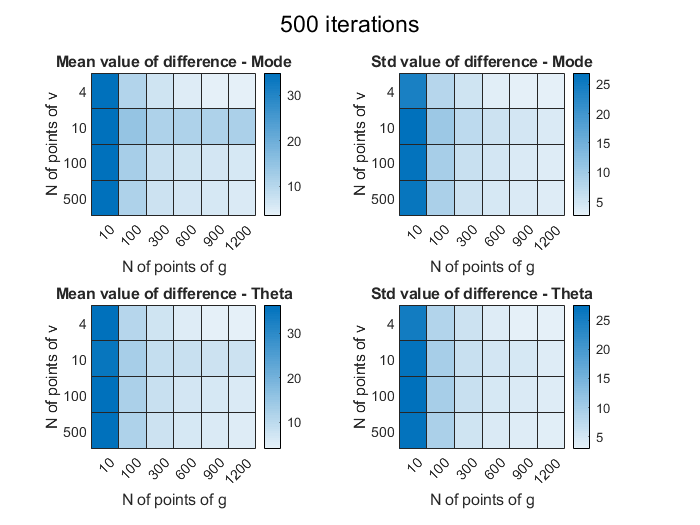

% Make other plot more simple
f = figure();
subplot(2,2,1)
heatmap(npoints_list_g,npoints_list_v,Mean_M);
xlabel('N of points of g')
ylabel('N of points of v')
title('Mean value of difference - Mode')
subplot(2,2,2)
heatmap(npoints_list_g,npoints_list_v,Std_M);
xlabel('N of points of g')
ylabel('N of points of v')
title('Std value of difference - Mode')
subplot(2,2,3)
heatmap(npoints_list_g,npoints_list_v,Mean_Theta);
xlabel('N of points of g')
ylabel('N of points of v')
title('Mean value of difference - Theta')
subplot(2,2,4)
heatmap(npoints_list_g,npoints_list_v,Std_Theta);
xlabel('N of points of g')
ylabel('N of points of v')
title('Std value of difference - Theta')
sgtitle(sprintf('%d iterations',max(iter_list)))
% Save figure
saveas(f,fullfile(path,'ImagesResults','Accuracy & Reproducibility- g & v noise.png'))

**Comments:**

Even with uncertainty in v's the solver is able to get to a solution quite close to the real one. 

It can be seen that for lower number of points of g that error differ a lot iteration to iteration, while for other bigger number of points the errors are more similar and tend to converge to a unique value, especially with the increase in number of g's. As for the number of velocity functions, that doesn't seem to affect that much (but not totally sure). This can also be due, to the fact that there is not many dispersion in the velocity values.

## Several Equations 1 & One Equation 2 - real g's, simulated v

close all

% Load files
cd(fullfile(path,'Example_images'))
file = dir('g_ratio.nii');
header = spm_vol(file.name);
gratio = spm_read_vols(header);

file = dir('Occipital_mask_tract.nii');
header = spm_vol(file.name);
tract = spm_read_vols(header);

g_map = gratio.*tract;
G     = g_map(find(g_map>0));

% Plot distribution of g's in data
figure()
histogram(G,20)
ylabel('Number of samples')
xlabel('G-ratio value')
title('Distribution of g-ratios in tract')

% Initiate
v       = 10;
alpha   = 0.1;
beta    = 0.7;

% Solve equations
x0      = [0.3;0.1]; % First guess on M and theta
options = optimoptions('lsqnonlin', 'Display','off','FunctionTolerance',10^-7,'OptimalityTolerance',10^-6,'algorithm','trust-region-reflective');
res    = lsqnonlin(@(x) make_equations_gv(x,alpha,beta,G,[v]),x0,[0.1 0],[1 1],options); % other option
% Get values for M and theta
M_data        = res(1);
Theta_data    = res(2);

sprintf('fsolver - Mode is: %.003f and Theta is: %.003f',M_data,Theta_data)

ans = 'fsolver - Mode is: 0.369 and Theta is: 0.247'

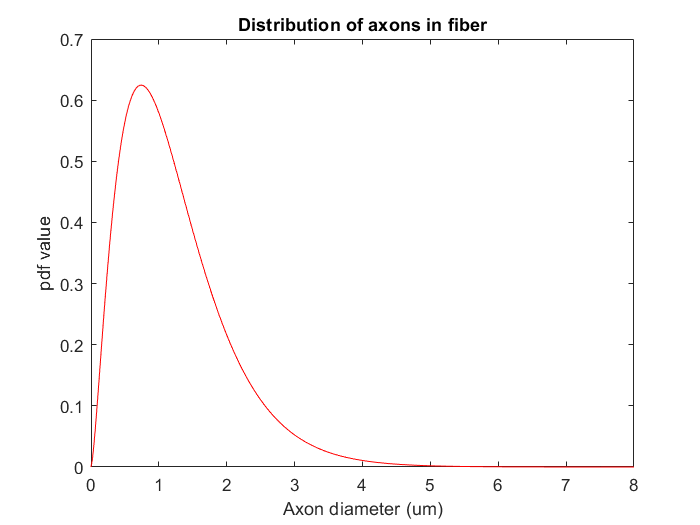

% Display gamma distribution
theta       = Theta_data;
mode        = M_data;
shape       = mode/theta+1;
X           = (0:0.01:4);
pdf         = gampdf(X*2,shape,theta);
pdf_save    = pdf;

figure()
t   =  plot(X,pdf,'r');
title('Distribution of axons in fiber')
xlabel('Axon diameter (um)')
ylabel('pdf value')

## Several Equations 1 & several Equation 2 - real g's, simulated v's

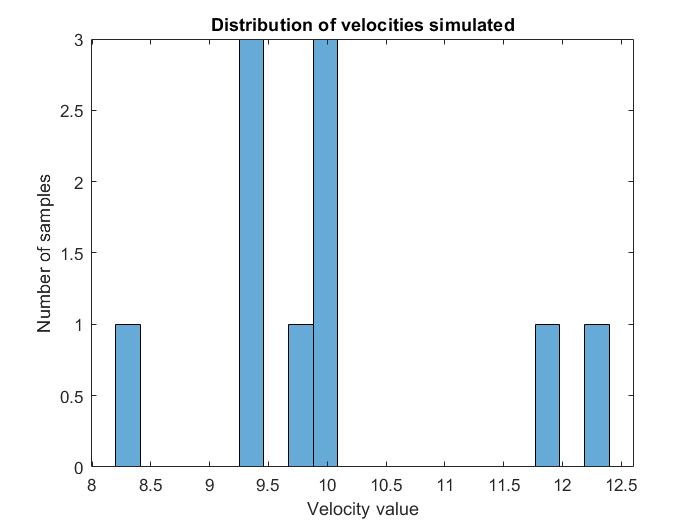

close all

% Load files
cd(fullfile(path,'Example_images'))
file = dir('g_ratio.nii');
header = spm_vol(file.name);
gratio = spm_read_vols(header);

file = dir('Occipital_mask_tract.nii');
header = spm_vol(file.name);
tract = spm_read_vols(header);

g_map = gratio.*tract;
G     = g_map(find(g_map>0));

% Initiate
v       = 10;
alpha   = 0.1;
beta    = 0.7;
npoints = 10;
V       = normrnd(v,1,[npoints,1]);

% Plot distribution of g's in data
figure()
histogram(V,20)
ylabel('Number of samples')
xlabel('Velocity value')
title('Distribution of velocities simulated')

% Solve equations
x0      = [0.3;0.1]; % First guess on M and theta
options = optimoptions('lsqnonlin', 'Display','off','FunctionTolerance',10^-7,'OptimalityTolerance',10^-6,'algorithm','trust-region-reflective');
res    = lsqnonlin(@(x) make_equations_gv(x,alpha,beta,G,V),x0,[0 0],[1 1],options); % other option
% Get values for M and theta
M_data        = res(1);
Theta_data    = res(2);

sprintf('fsolver - Mode is: %.003f and Theta is: %.003f',M_data,Theta_data)

ans = 'fsolver - Mode is: 0.375 and Theta is: 0.245'

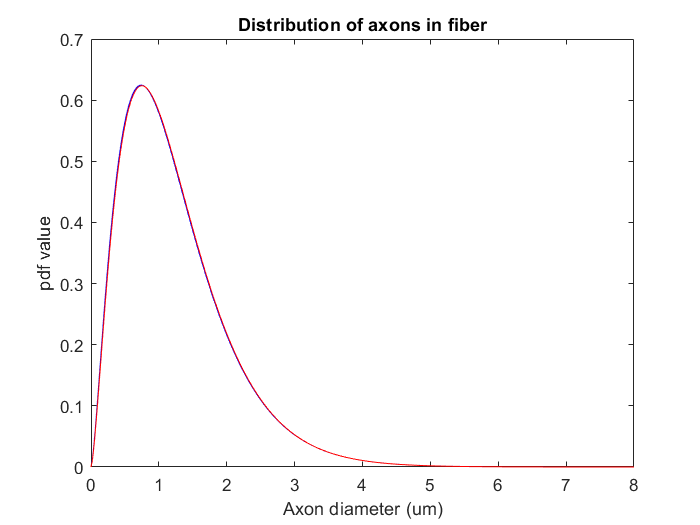


% Display gamma distribution
figure()
plot(X,pdf_save,'b'); % display previous graph with uncertainty just in g
hold on
theta       = Theta_data;
mode        = M_data;
shape       = mode/theta+1;
X           = (0:0.01:4);
pdf         = gampdf(X*2,shape,theta);
hold on
plot(X,pdf,'r');
title('Distribution of axons in fiber')
xlabel('Axon diameter (um)')
ylabel('pdf value')

**Comments:**

There doesn't seem a lot of difference between adding the velocity equations, when compared to the previous case.And it was added only 10 sample points for velocity with 1 m/s standard deviation.

## Several Equations 1 & several Equation 2 - real g's, simulated v's - Testing Sampling Stratagies

ans = 'For the tract and velocity = 10 m/s- Mode is: 0.371 and Theta is: 0.247'

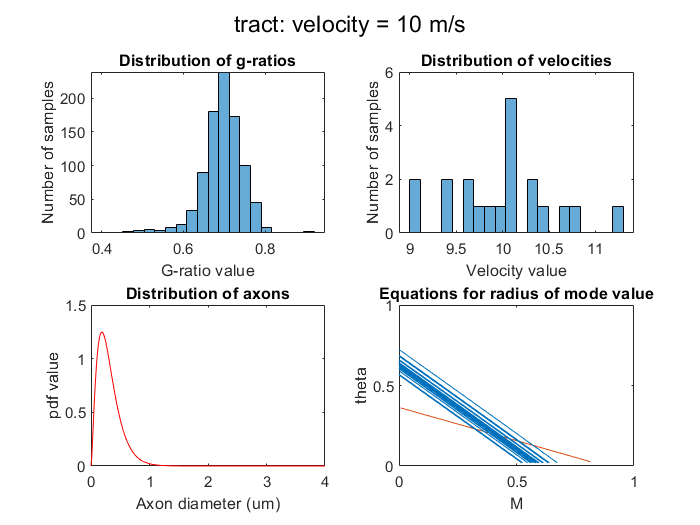

ans = 'For the tract and velocity = 14 m/s- Mode is: 0.819 and Theta is: 0.061'

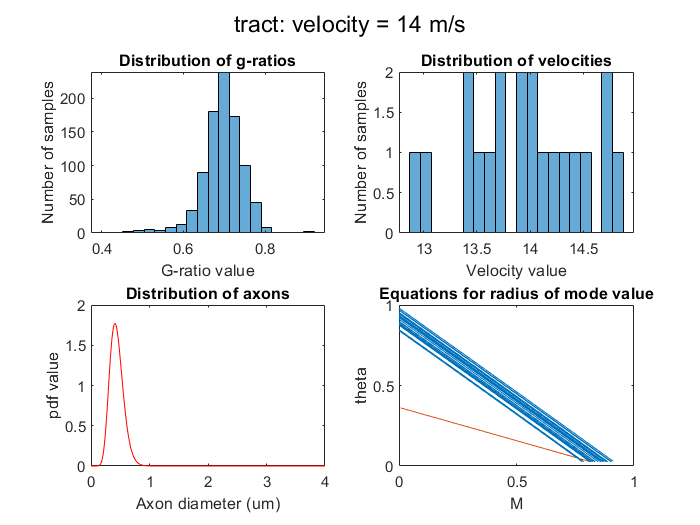

ans = 'For the CC and velocity = 10 m/s- Mode is: 0.000 and Theta is: 0.633'

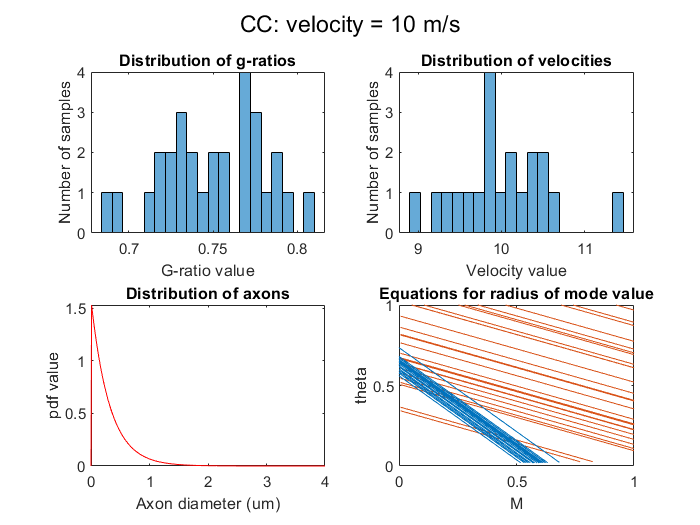

ans = 'For the CC and velocity = 14 m/s- Mode is: 0.109 and Theta is: 0.794'

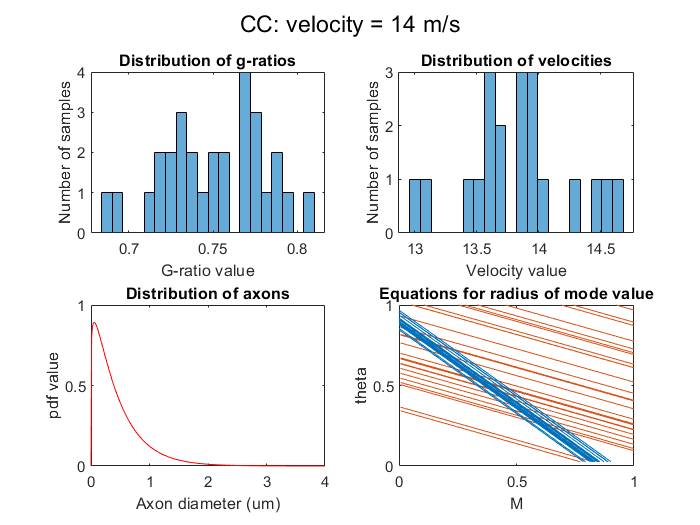

close all
type_list = {'tract','CC'};

% Loop for all mask and ROI of tract
for i=1:length(type_list)
    type=type_list{i};
    
    % Load files
    cd(fullfile(path,'Example_images'))
    file = dir('g_ratio.nii');
    header = spm_vol(file.name);
    gratio = spm_read_vols(header);
    
    file = dir(strcat('Occipital_mask_',type,'.nii'));
    header = spm_vol(file.name);
    tract = spm_read_vols(header);
    
    g_map = gratio.*tract;
    G     = g_map(find(g_map>0));
    
    v_list = [10,14];
    for v_i=1:length(v_list)
        % Initiate
        v       = v_list(v_i);
        alpha   = 0.1;
        beta    = 0.7;
        npoints = 20;
        V       = normrnd(v,0.5,[npoints,1]);
        
        % Plot distribution of g's in data
        figure()
        subplot(2,2,1)
        histogram(G,20)
        ylabel('Number of samples')
        xlabel('G-ratio value')
        title('Distribution of g-ratios')
        hold on
        subplot(2,2,2)
        histogram(V,20)
        ylabel('Number of samples')
        xlabel('Velocity value')
        title('Distribution of velocities')
        hold on
        
        % Solve equations
        x0      = [0.3;0.1]; % First guess on M and theta
        options = optimoptions('lsqnonlin', 'Display','off','FunctionTolerance',10^-6,'OptimalityTolerance',10^-6,'algorithm','trust-region-reflective');
        res    = lsqnonlin(@(x) make_equations_gv(x,alpha,beta,G,V),x0,[0 0],[1 1],options); % other option
        % Get values for M and theta
        M_data        = res(1);
        Theta_data    = res(2);
        
        sprintf('For the %s and velocity = %d m/s- Mode is: %.003f and Theta is: %.003f',type,v,M_data,Theta_data)
        
        % Display gamma distribution for diameter
        theta       = Theta_data;
        mode        = M_data;
        shape       = mode/theta+1;
        X           = (0:0.01:4);
        pdf         = gampdf(X*2,shape,theta);
        
        subplot(2,2,3)
        t   =  plot(X,pdf,'r');
        title('Distribution of axons')
        xlabel('Axon diameter (um)')
        ylabel('pdf value')
        sgtitle(sprintf('%s: velocity = %d m/s',type,v))
        
        % Display equations
        clearvars mode
        subplot(2,2,4)
        if i==2
            for index=1:length(G)
                warning('off')
                fimplicit(@(M,theta) make_equations_g_plot(M,theta,G(index),alpha,beta),'Color',[0.8500, 0.3250, 0.0980]);
                hold on
            end
        else
            warning('off')
            fimplicit(@(M,theta) make_equations_g_plot(M,theta,mode(round(G,3)),alpha,beta),'Color',[0.8500, 0.3250, 0.0980]);
            hold on
        end
        
        for index=1:length(V)
            warning('off')
            fimplicit(@(M,theta) make_equations_v_plot(M,theta,V(index),alpha,beta),'Color',[0, 0.4470, 0.7410]);
            hold on
        end
        xlim([0,1])
        ylim([0,1])
        xlabel('M')
        ylabel('theta')
        title('Equations for radius of mode value')
        
    end
end

**Comments:**

If we consider the whole mask of the tract we get a normal distribution, on the other hand if we consider just a ROI in the corpos callosum we don't have enought voxels to know if it is a normal distribution, anyway the values are larger than when considering the whole tract.

For this reason, the pair of modes and thetas that we found is not feasile and we don't get a feasible solution. But, if we increase the velocity from 7 to 9 when considering the corpos callosum ROI only, we get a better result, with a feasible solution, which is according to expected becuase higher values of g should correspond to higher velocities.

## Several Equations 1 & Several Equation 2 (Sample M and Theta space)

Sample M and Theta space for several iterations

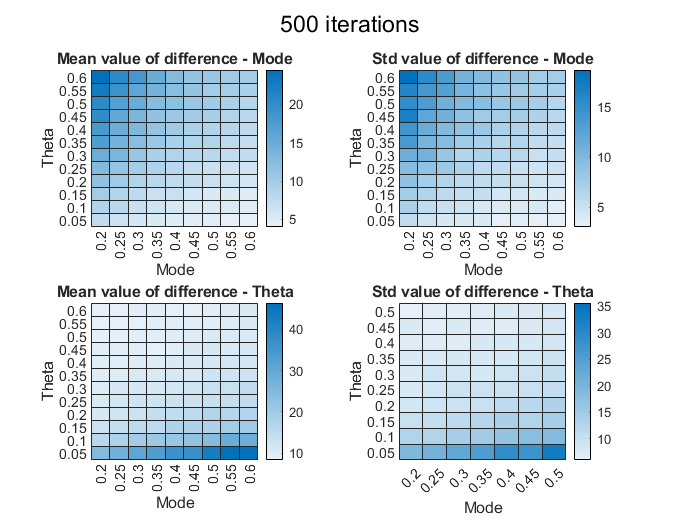

% Initiate
alpha           = 0.1;
beta            = 0.7;
npoints_theta   = 0.6:-0.05:0.05;
npoints_mode    = 0.2:0.05:0.6;
iter_list       = 1:500;
Mean_M          = zeros(length(npoints_theta),length(npoints_mode));
Std_M           = zeros(length(npoints_theta),length(npoints_mode));
Mean_Theta      = zeros(length(npoints_theta),length(npoints_mode));
Std_Theta       = zeros(length(npoints_theta),length(npoints_mode));
G_vector        = zeros(length(npoints_theta),length(npoints_mode));
V_vector        = zeros(length(npoints_theta),length(npoints_mode));
close all


% Loop through Thetas
for i=1:length(npoints_theta)
    
    Diff_M     = [];
    Diff_Theta = [];
    
    % Loop through iterations
    for iter=1:length(iter_list)
        
        theta       = npoints_theta(i);
        mode_diff   = [];
        theta_diff  = [];
        
        % Loop through Modes
        for j=1:length(npoints_mode)
            % Initiate
            mode        = npoints_mode(j);
            alpha       = 0.1;
            beta        = 0.7;
            npoints_g   = 200; % Selectec base on previous analysis
            npoints_v   = 20; % Selectec base on previous analysis
            
            % Get real values
            g_real   = sqrt(beta^2*theta^(2*alpha) ...
                * gamma(mode/theta+1)/gamma(mode/theta+1-2*alpha) ...
                * (mode + 3*theta + 2*(theta^2)/mode) ...
                / (mode + (3 - 4*alpha)*theta + (2+4*alpha^2-6*alpha)*(theta^2)/mode));
            
            v_real   =  ((2*5.5)/beta)*theta^(1-alpha) ...
                * gamma(mode/theta+1-alpha)/gamma(mode/theta+1) ...
                * (mode/theta+1-alpha);
            
            % Save vector to visualize
            G_vector(i,j)    = g_real;
            V_vector(i,j)    = v_real;
            
            % Add noise to real values of g and v
            G       = normrnd(g_real,0.05,[npoints_g,1]);  % Make gaussian noise on g's with mean real and std of 0.02.
            V       = normrnd(v_real,0.5,[npoints_v,1]);  % Make gaussian noise on v's with mean real and std of 0.2.
            
            % Solve equations
            x0      = [0.3;0.1]; % First guess on M and theta
            options = optimoptions('lsqnonlin','Display','off','FunctionTolerance',10^-7,'OptimalityTolerance',10^-6,'algorithm','trust-region-reflective');
            res     = lsqnonlin(@(x) make_equations_gv(x,alpha,beta,G,V),x0,[0 0],[1 1],options); % other option
            M_with_noise        = res(1);
            Theta_with_noise    = res(2);
            
            % Calculate difference between true and noise values
            mode_diff          = [mode_diff (abs(mode - M_with_noise)/mode)*100];
            theta_diff         = [theta_diff (abs(theta - Theta_with_noise)/theta)*100];
        end
        Diff_M     = [Diff_M; mode_diff];
        Diff_Theta = [Diff_Theta; theta_diff];
    end
    
    Mean_M(i,:)       = mean(Diff_M);
    Std_M(i,:)        = std(Diff_M);
    Mean_Theta(i,:)   = mean(Diff_Theta);
    Std_Theta(i,:)    = std(Diff_Theta);
    
end

% Plot figures
figure(1)
subplot(2,2,1)
heatmap(npoints_mode,npoints_theta,Mean_M);
xlabel('Mode')
ylabel('Theta')
title('Mean value of difference - Mode')
subplot(2,2,2)
heatmap(npoints_mode,npoints_theta,Std_M);
xlabel('Mode')
ylabel('Theta')
title('Std value of difference - Mode')
subplot(2,2,3)
heatmap(npoints_mode,npoints_theta,Mean_Theta);
xlabel('Mode')
ylabel('Theta')
title('Mean value of difference - Theta')
subplot(2,2,4)
heatmap(npoints_mode,npoints_theta,Std_Theta);
xlabel('Mode')
ylabel('Theta')
title('Std value of difference - Theta')
sgtitle(sprintf('%d iterations',iter))
% Save figure
saveas(gcf,fullfile(path,'ImagesResults','Mode & Theta space.png'))

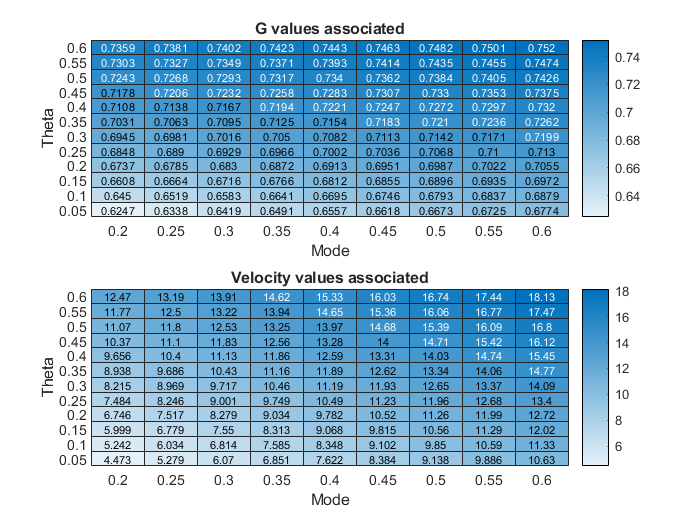


% Plot real g and v values
figure(2)
subplot(2,1,1)
heatmap(npoints_mode,npoints_theta,G_vector);
xlabel('Mode')
ylabel('Theta')
title('G values associated')
subplot(2,1,2)
heatmap(npoints_mode,npoints_theta,V_vector);
xlabel('Mode')
ylabel('Theta')
title('Velocity values associated')
% Save figure
saveas(gcf,fullfile(path,'ImagesResults','Mode & Theta space - g & v values.png'))

**Comments:**

For lower thetas, the distribution is approximated by a gaussian one, so it is normal that there is a high uncertainty there.

## Test different tracts

ans = 'For the Occipital and velocity = 10.0 m/s- Mode is: 0.295 and Theta is: 0.332'

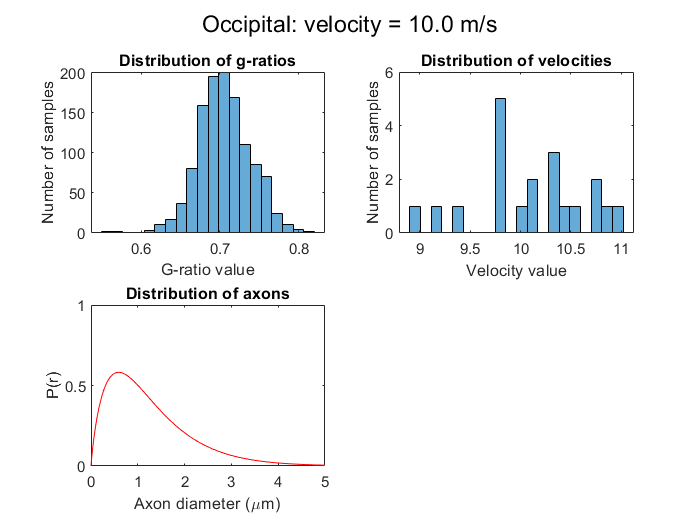

ans = 'For the Orbitofrontal and velocity = 8.0 m/s- Mode is: 0.341 and Theta is: 0.137'

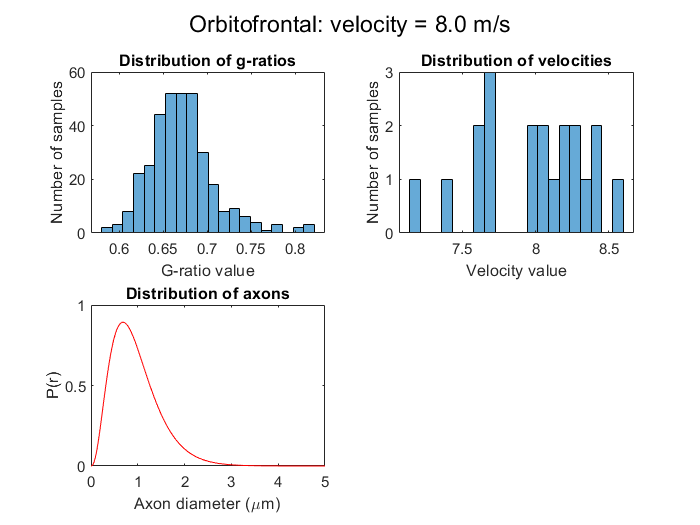

cd(fullfile(path,'Example_images\PR00639_VS160649'))

% Load g-ratio
file = dir('g_ratio.nii');
header = spm_vol(file.name);
gratio = spm_read_vols(header);

tract_list = {'Occipital','Orbitofrontal'};
v_list     = [10,8];

% Loop for all mask and ROI of tract
for i=1:length(tract_list)
    tract_name=tract_list{i};
    
    % Load tracts
    file = dir(strcat(tract_name,'_mask.nii'));
    header = spm_vol(file.name);
    tract = spm_read_vols(header);
    
    g_map = gratio.*tract;
    G     = g_map(find(g_map>0));
      
    v       = v_list(i);
    alpha   = 0.1;
    beta    = 0.7;
    npoints = 20;
    V       = normrnd(v,0.5,[npoints,1]);
    
    % Plot distribution of g's in data
    figure()
    subplot(2,2,1)
    histogram(G,20)
    ylabel('Number of samples')
    xlabel('G-ratio value')
    title('Distribution of g-ratios')
    hold on
    subplot(2,2,2)
    histogram(V,20)
    ylabel('Number of samples')
    xlabel('Velocity value')
    title('Distribution of velocities')
    hold on
    
    % Solve equations
    x0      = [0.3;0.1]; % First guess on M and theta
    options = optimoptions('lsqnonlin', 'Display','off','FunctionTolerance',10^-6,'OptimalityTolerance',10^-6,'algorithm','trust-region-reflective');
    res    = lsqnonlin(@(x) make_equations_gv(x,alpha,beta,G,V),x0,[0 0],[1 1],options); % other option
    
    % Get values for M and theta
    M_data        = res(1);
    Theta_data    = res(2);
    
    sprintf('For the %s and velocity = %0.1f m/s- Mode is: %.003f and Theta is: %.003f',tract_name,v,M_data,Theta_data)

    % Display gamma distribution for diameter
    theta       = Theta_data*2;
    mode        = M_data*2;
    shape       = mode/theta+1;
    X           = (0:0.01:2.5)*2;
    pdf         = gampdf(X,shape,theta);
    
    subplot(2,2,3)
    t   =  plot(X,pdf,'r');
    title('Distribution of axons')
    xlabel('Axon diameter ({\mu}m)')
    ylabel('P(r)')
    ylim([0 1])
    xlim([0 5])
    sgtitle(sprintf('%s: velocity = %0.1f m/s',tract_name,v))
    
    % Display equations
%     clearvars mode
%     subplot(2,2,4)
%     if i==2
%         for index=1:length(G)
%             warning('off')
%             fimplicit(@(M,theta) make_equations_g_plot(M,theta,G(index),alpha,beta),'Color',[0.8500, 0.3250, 0.0980]);
%             hold on
%         end
%     else
%         warning('off')
%         fimplicit(@(M,theta) make_equations_g_plot(M,theta,mode(round(G,3)),alpha,beta),'Color',[0.8500, 0.3250, 0.0980]);
%         hold on
%     end
%     
%     for index=1:length(V)
%         warning('off')
%         fimplicit(@(M,theta) make_equations_v_plot(M,theta,V(index),alpha,beta),'Color',[0, 0.4470, 0.7410]);
%         hold on
%     end
%     xlim([0,1])
%     ylim([0,1])
%     xlabel('M')
%     ylabel('theta')
%     title('Equations for radius of mode value')
    
    % Save figure
    saveas(gcf,fullfile(path,'ImagesResults',sprintf('ExampleSolution_%s.png',tract_name)))

end

**Comments:**

If the assumptions made to the velocity are right, results seem to be consistent with literature: the occipital tract having more fatter axons than the orbitofrontal one. Also the mode values seem to be similar between the 2 cases, "confirming" the assumption of constant mode.

The mean diameters (Mode + Theta)*2 are 1.51 um and 0.95 um for the occipital and orbitofrontal tracts respectively.

## Test different masks for the same tract

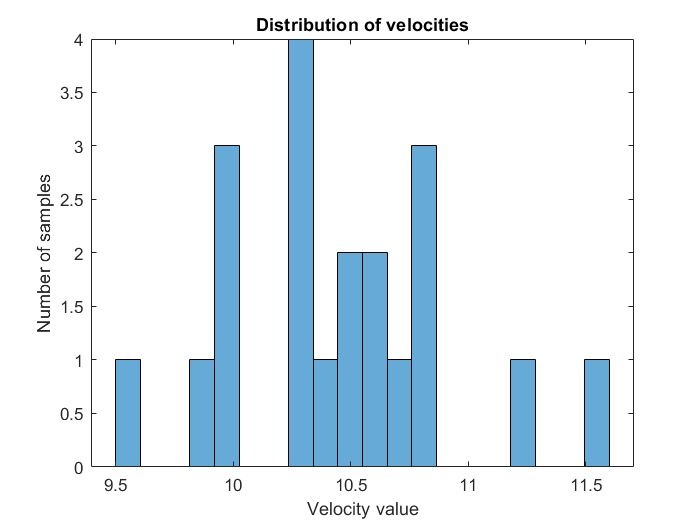

cd(fullfile(path,'Example_images\PR00639_VS160649'))

% Load g-ratio
file = dir('g_ratio.nii');
header = spm_vol(file.name);
gratio = spm_read_vols(header);

tract_list = {'Occipital','Occipital_high_thr','All_fibers'};

figure()
v       = 10.5;
npoints = 20;
V       = normrnd(v,0.5,[npoints,1]);
histogram(V,20)
ylabel('Number of samples')
xlabel('Velocity value')
title('Distribution of velocities')

ans = 'For the Occipital and velocity = 10.5 m/s- Mode is: 0.335 and Theta is: 0.316'

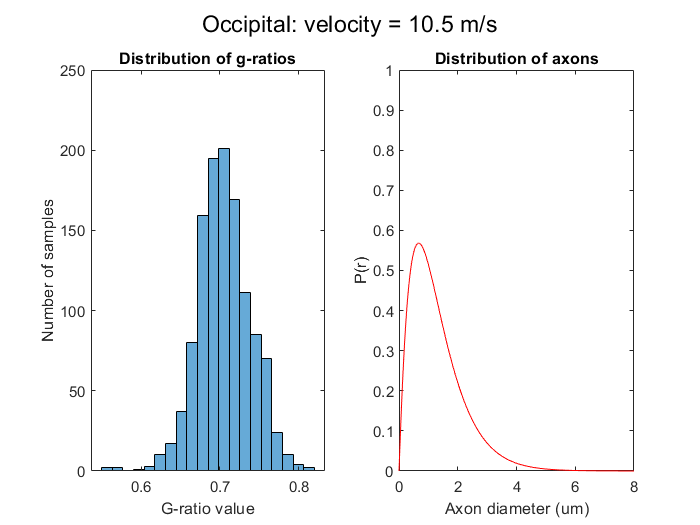

ans = 'For the Occipital_high_thr and velocity = 10.5 m/s- Mode is: 0.329 and Theta is: 0.321'

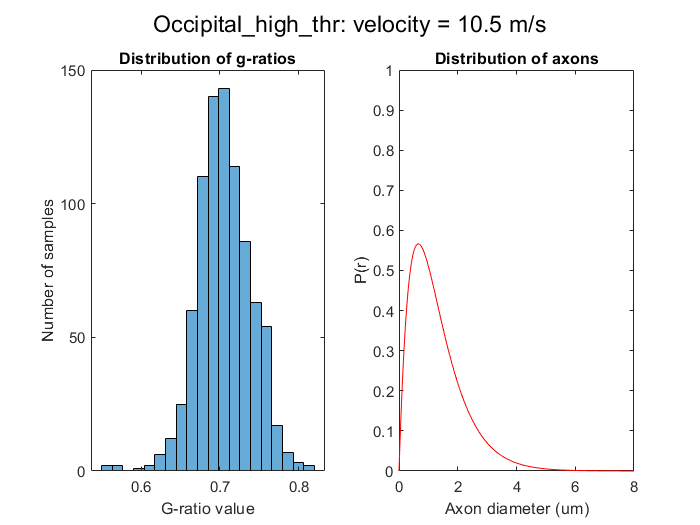

ans = 'For the All_fibers and velocity = 13.0 m/s- Mode is: 0.369 and Theta is: 0.454'

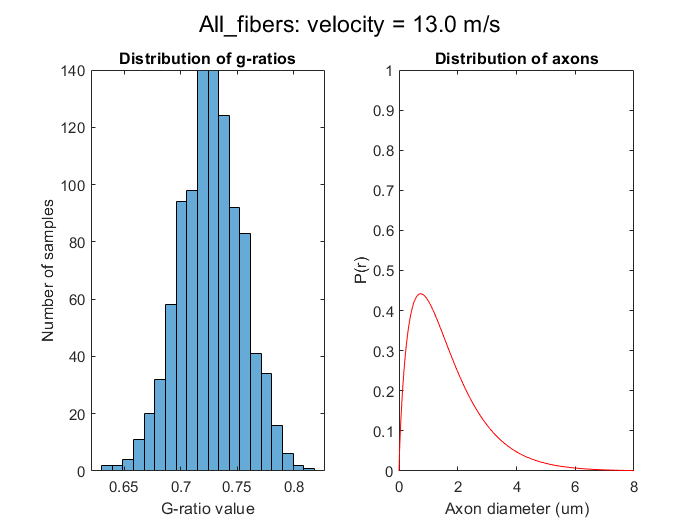

    
% Loop for all mask and ROI of tract
for i=1:length(tract_list)
    
    tract_name = tract_list{i};
    
    if i==1 || i==2
              
        % Load tracts
        file = dir(strcat(tract_name,'_mask.nii'));
        header = spm_vol(file.name);
        tract = spm_read_vols(header);
        
        g_map = gratio.*tract;
        G     = g_map(find(g_map>0));
    else
        G     = load('Vals_gratio_Occipital.mat');
        G     = G.gratio_vals_per_fiber;
        G     = G(find(G>0));
        sd    = std(G);
        med   = mean(G);
        G     = normrnd(med,sd,[1000,1]); 
        v     = 13;
        V     = normrnd(v,0.5,[npoints,1]);
    end
    
    alpha   = 0.1;
    beta    = 0.7;

    % Plot distribution of g's in data
    figure()
    subplot(1,2,1)
    histogram(G,20)
    ylabel('Number of samples')
    xlabel('G-ratio value')
    title('Distribution of g-ratios')
    hold on
    
    % Solve equations
    x0      = [0.3;0.1]; % First guess on M and theta
    options = optimoptions('lsqnonlin', 'Display','off','FunctionTolerance',10^-6,'OptimalityTolerance',10^-6,'algorithm','trust-region-reflective');
    res     = lsqnonlin(@(x) make_equations_gv(x,alpha,beta,G,V),x0,[0 0],[1 1],options); % other option
    
    % Get values for M and theta
    M_data        = res(1);
    Theta_data    = res(2);
    
    sprintf('For the %s and velocity = %0.1f m/s- Mode is: %.003f and Theta is: %.003f',tract_name,v,M_data,Theta_data)

    % Display gamma distribution for diameter
    theta       = Theta_data*2;
    mode        = M_data*2;
    shape       = mode/theta+1;
    X           = (0:0.01:4)*2;
    pdf         = gampdf(X,shape,theta);
    
    subplot(1,2,2)
    t   =  plot(X,pdf,'r');
    title('Distribution of axons')
    xlabel('Axon diameter (um)')
    ylabel('P(r)')
    ylim([0 1])
    sgtitle(sprintf('%s: velocity = %0.1f m/s',tract_name,v),'Interpreter', 'none')
    
    % Save figure
    saveas(gcf,fullfile(path,'ImagesResults',sprintf('ExampleSolution_%s.png',tract_name)))

end

**Comments:**

The mask used for this analysis has some impact. Thought the threshold applied to the second mask was not that big, and the distributions of g's are quite similar (the thing that differs the most is the the number of samples, but the distribution has really similar mean and std). As for the distribution of diameters, the second mask seems to have a longer tail, don't know exactly why. Maybe because it has lower sampling points.

The last case, where we consider all the values for all the fibers (so a voxel can be sampled more than once) produces a really big vector, for which I was not able to compute the solution. So, I assumed a distribution with that mean and std (the mean is higher than before and the std is lower). These therefore asks for a higher velocity, because with the same one used before we would get modes of 0.0someting.

# Definition of functions in Matlab

### [Core Function] Equation 1 & 2 - Together - several equations 1 & 2 (incertainty in g and v) 

function F = make_equations_gv(x,alpha,beta,G,V)
% Variables
M = x(1);
theta = x(2);

F = [];

% Velocity equations (add as much as the input askes)
for i=1:length(V)
    v = V(i);
    F = [F;
        -v + ((2*5.5)/beta)*theta^(1-alpha) ...
        * gamma(M/theta+1-alpha)/gamma(M/theta+1) ...
        * (M/theta+1-alpha)];
end

% G ratio equations (add as much as the input askes)
for i=1:length(G)
    g = G(i);
    F  = [F;
        -g^2 + beta^2*theta^(2*alpha) ...
        * gamma(M/theta+1)/gamma(M/theta+1-2*alpha) ... % Without approximmation
        * (M + 3*theta + 2*(theta^2)/M) ...
        / (M + (3 - 4*alpha)*theta + (2+4*alpha^2-6*alpha)*(theta^2)/M)];
end

end

### [Just to plot Function] Equation 1 (g-ratio):

function F = make_equations_g_plot(M,theta,g,alpha,beta)
F = [-g^2 + beta^2*theta^(2*alpha) ...
    * gamma(M/theta+1)/gamma(M/theta+1-2*alpha) ... % Without approximmation
    * (M + 3*theta + 2*(theta^2)/M) ...
    / (M + (3 - 4*alpha)*theta + (2+4*alpha^2-6*alpha)*(theta^2)/M)];
end

### [Just to plot Function] Equation 2 (velocity):

function F = make_equations_v_plot(M,theta,v,alpha,beta)
F = [-v + ((2*5.5)/beta)*theta^(1-alpha) ...
    * gamma(M/theta+1-alpha)/gamma(M/theta+1) ... % Without approximmation
    * (M/theta+1-alpha)];
end

### [Auxiliar Function] Plot and Solve

function  [M_true,Theta_true] = GetRealSol_Plot(i,npoints_list,alpha,beta,g,v,M_with_noise,Theta_with_noise,c,plot_bool)

% Solve equations
x0      = [0.3, 0.1];
options = optimoptions('lsqnonlin','Display','Off','FunctionTolerance',10^-7,'OptimalityTolerance',10^-6,'algorithm','trust-region-reflective');
res     = lsqnonlin(@(x) make_equations_gv(x,alpha,beta,[g],[v]),x0,[0 0],[1 1],options); % other option

% Get solutions
M_true              = res(1);
Theta_true          = res(2);

sprintf('Real Mode is: %.003f and Theta is: %.003f',M_true,Theta_true);

% Calculate difference between true and noise values
diff_M          = (abs(M_true - M_with_noise)/M_true)*100;
diff_Theta      = (abs(Theta_true - Theta_with_noise)/Theta_true)*100;

sprintf('Difference in mode is: %.003f and in theta is: %.003f',diff_M,diff_Theta);

if plot_bool==1
    % Display differences in M and Theta (absolute)
    figure(2)
    subplot(2,1,1)
    scatter(npoints_list(i),diff_M,'Filled','MarkerFaceColor',c)
    xlim([0 max(npoints_list)])
    xlabel('N of points')
    ylabel('% Difference')
    title('Accuracy in M')
    hold on
    subplot(2,1,2)
    scatter(npoints_list(i),diff_Theta,'Filled','MarkerFaceColor',c)
    hold off
    xlim([0 max(npoints_list)])
    xlabel('N of points')
    ylabel('% Difference')
    title('Accuracy in Theta')
    hold on
    
    % Display Gamma functions (true and noisy) for the several number of
    % g's equations for diameter
    theta       = Theta_true;
    mode        = M_true;
    shape       = mode/theta+1;
    X           = (0:0.01:4);
    pdf_true    = gampdf(X*2,shape,theta);
    
    
    theta       = Theta_with_noise;
    mode        = M_with_noise;
    shape       = mode/theta+1;
    X           = (0:0.01:4);
    pdf_noise   = gampdf(X*2,shape,theta);
    
    if i<=4
        figure(3)
        subplot(1,4,i)
        t   =  plot(X,pdf_true,'r');
        hold on
        n   = plot(X,pdf_noise,'b');
        hold on
        title(sprintf('%d points',npoints_list(i)))
        xlabel('Axon diameter (um)')
        ylabel('pdf value')
        legend([t, n],'True value','Noise value')
        hold on
    end
end

end